# Calcolo Numerico con Laboratorio

# Compito a casa 

# 27 settembre 2021

## Esercizio 1 

Si consideri la funzione 

$f(x)=\frac1{(e^{x+0.2}-1)^2+0.05}+\frac{10}{\cos(x)+1.2}$   per $x\in[-3,7]$.

- Per ogni valore di `n=1:3:10 `calcolare il polinomio interpolatore di grado `n` utilizzando `n+1` nodi equispaziati nell'intervallo dato.

- Calcolare l'errore massimo per ciascun valore di `n`.

- Riportare in 4 figure la funzione con i polinomi interpolatori di grado diverso. Completare le figure con la legenda e il titolo. 

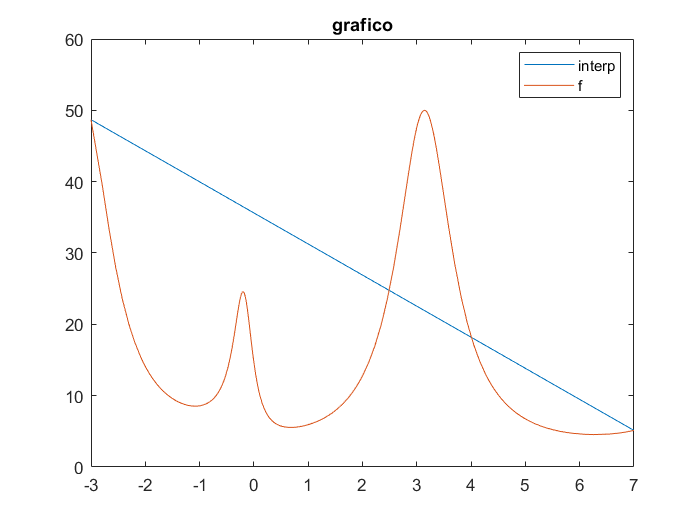

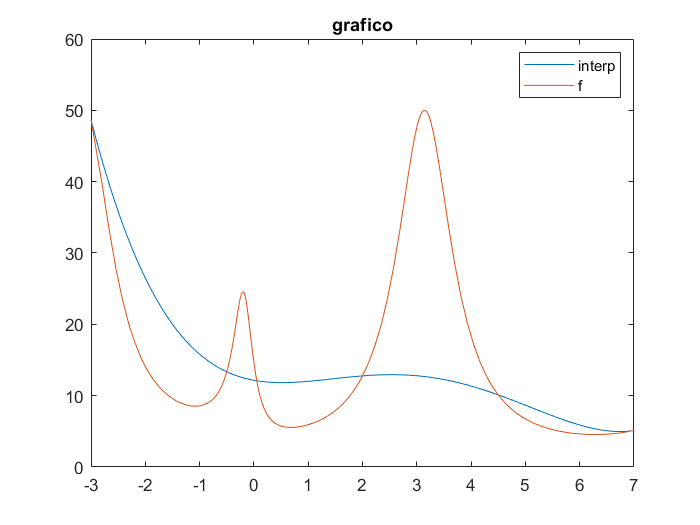

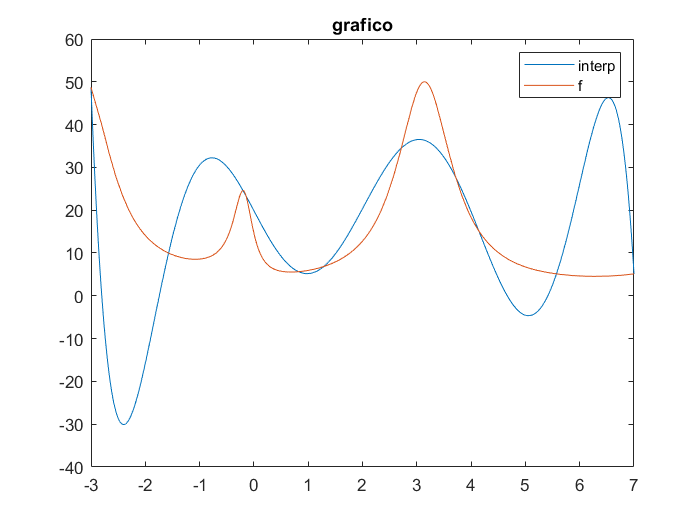

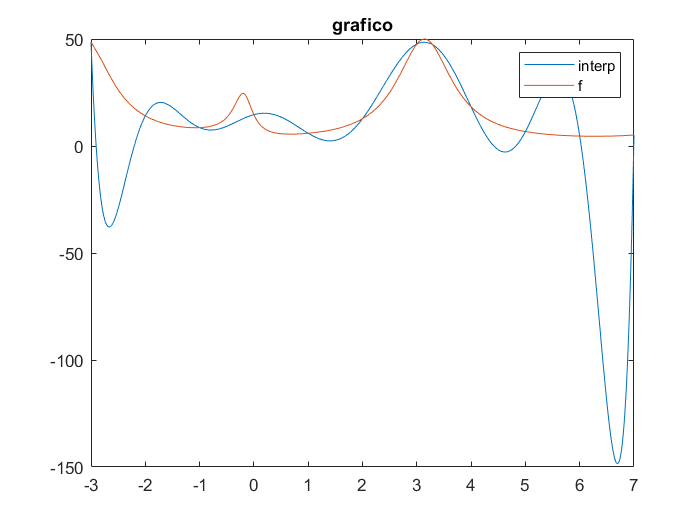

clear all
close all
f=@(x) 1./((exp(x+0.2)-1).^2+0.05)+10./(cos(x)+1.2);
int=[-3 7];
n=1:3:10;
E=[];
z=linspace(-3,7,100);
for i=1:length(n)
    p=calcPoly(f,int,n(i));
    E=[E norm(errorFunction(z,f,p),"inf")];
    figure
    plotPoly(p,int)
    hold on
    fplotSave({f},int,"grafico",["interp","f"])
end

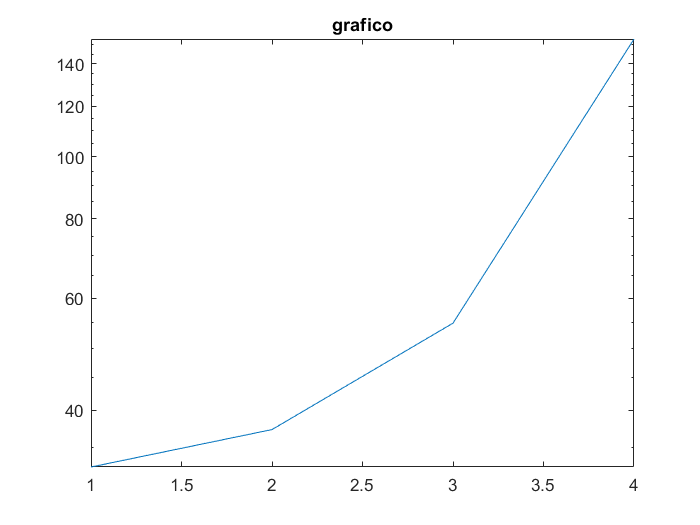

figure
semilogySave({[1:length(E)]},{E},"grafico")

## Esercizio 2

Si consideri la funzione $f(x)=e^x$, per $x\in[-1,1]$.

- Interpolare con polinomi di grado **pari** $n=2,\dots,12$, la funzione data, usando $n+1$ punti equispaziati nell'intervallo $[-1,1]$.

- Riportare il grafico di ciascun polinomio interpolatore insieme con quello della funzione data.

- Calcolare l'errore commesso ossia    $E_n=\max_{a\le x\le b}|f(x)-\Pi_n(x)|$.

- Costruire un vettore contenente gli errori ottenuti per tutti i valori di $n$ e riportare gli errori in un grafico in scala semilogaritmica `semilogy(n,E) `essendo `n` ed `E`  i vettori contenenti rispettivamente i valori dei gradi dei polinomi usati e i corrispondenti valori dell'errore.

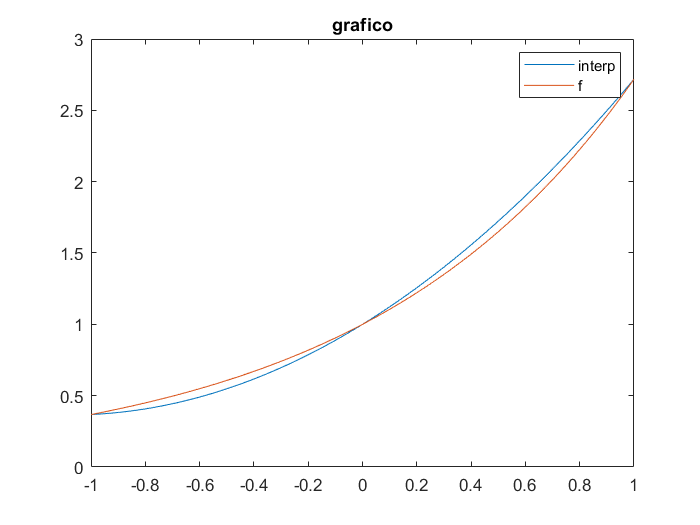

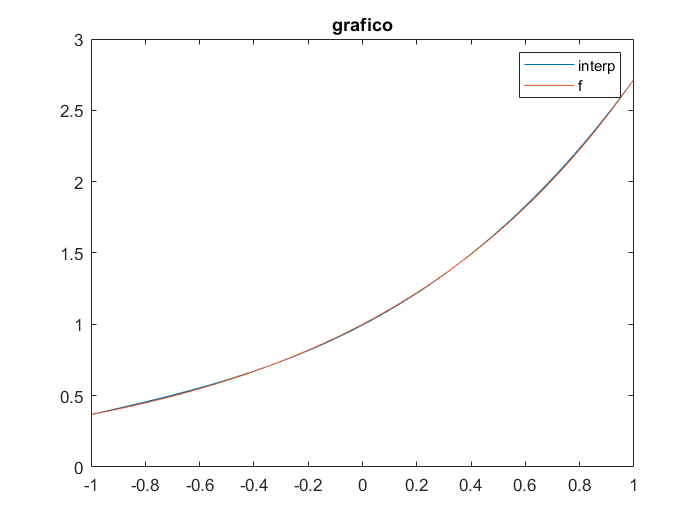

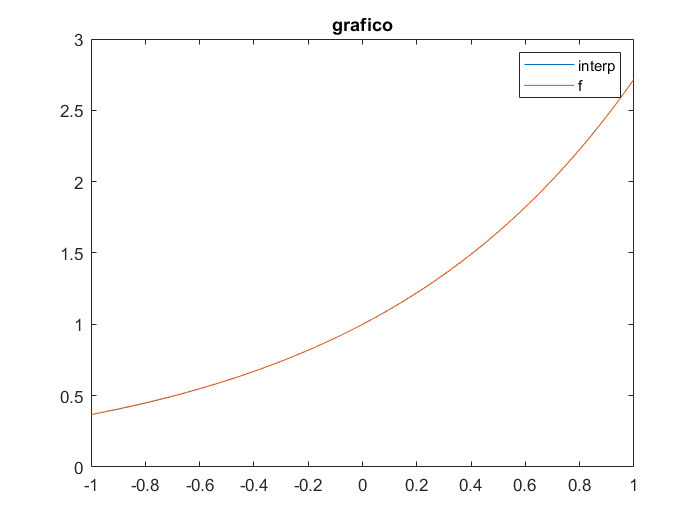

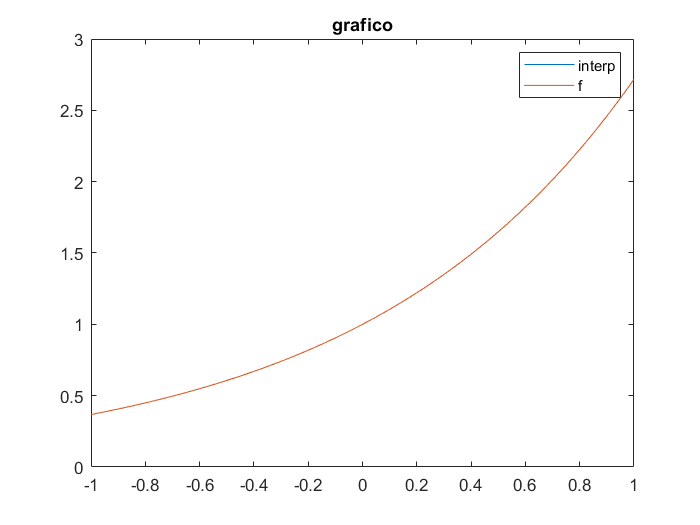

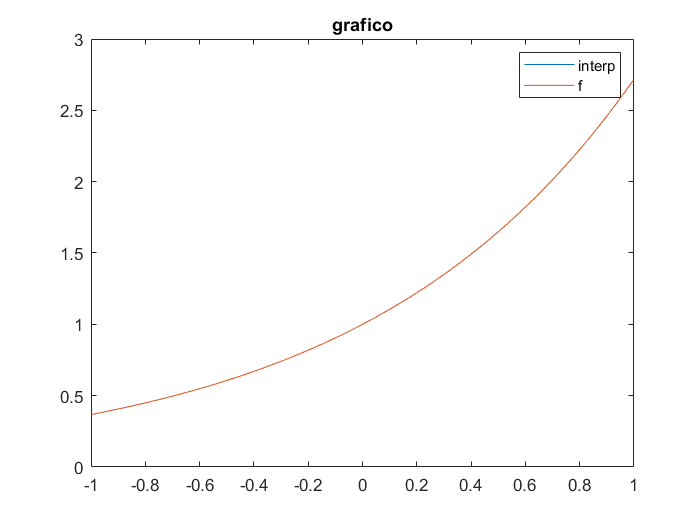

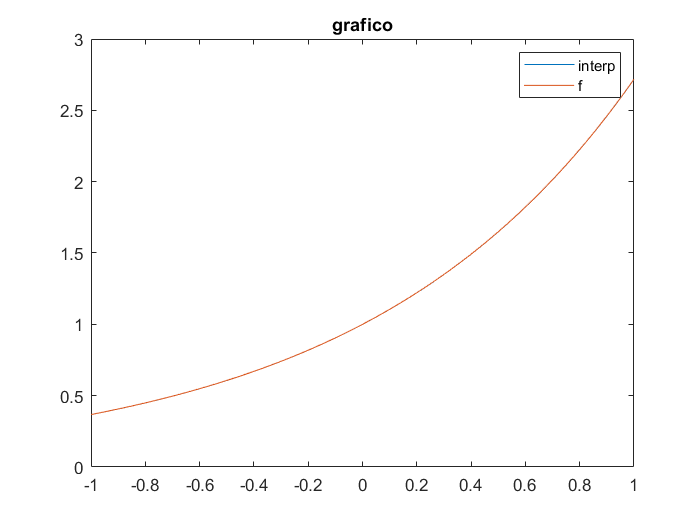

clear all
close all
f=@(x) exp(x);
int=[-1 1];
E=[];
z=linspace(-1,1,120);
for n=2:12
    p=calcPoly(f,int,n);
    figure
    plotPoly(p,int)
    hold on
    fplotSave({f},int,"grafico",["interp","f"])
    E=[E norm(errorFunction(z,f,p),"inf")];
end

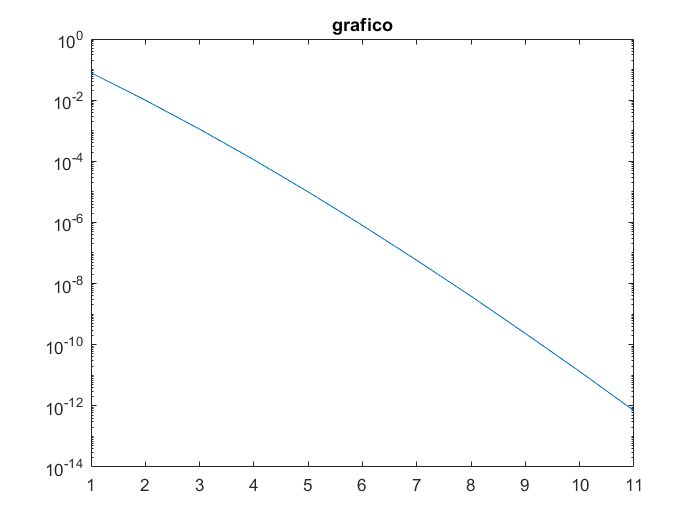

figure
semilogySave({[1:length(E)]},{E},"grafico")